# [Q8] MUTUAL COUPLING

Created by: Prof F Gonzalez-Longatt, 09.02.2019 

Document available at: [ResearchGate](https://www.researchgate.net/publication/338076702_TUTORIAL_Ideal_Two-winding_power_transformer)

DOI: [10.13140/RG.2.2.16327.85923](https://www.researchgate.net/deref/http%3A%2F%2Fdx.doi.org%2F10.13140%2FRG.2.2.16327.85923?_sg%5B0%5D=YODqr8lUC06krCLuHg1BoE9mY5qezkWzIUxCV0DmGjNNAkt2ko2S-K7aAl_WeMflGHrpPVcu4nEDH629k7MCVMvPJA.mVSFRNpv-yDPME3Qi57BQAKClwG3aAfLKwxRKAIXYpZGKw0ppLSDza4McWefQVZnxzztkv2edvlMMY5RYXLBVw)

[Q8] In Fig. Q.8, calculate the current flowing in the secondary circuit when Vs = 200<0 V

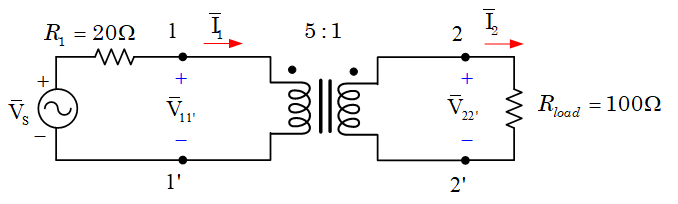

Figure [Q8]

clc
clear
fprintf(' SOLUTION [Q8]\n')

Vs = 200* exp(+i * 0 * pi/180);  % Vs: Supply voltage -Phasor, RMS
w = 1000;                        % w : Angular speed (rad/sec)
f = w/(2*pi);                    % f: frequency (Hz)
a = 5/1;                         % a: Transformer ratio
R1 = 20;                         % R1: Primary resistance in series connection (Ohms)
Rload = 100;                     % Rload: Load resistor in Ohms.

## Refering the load (Rload) to the primary side (Rload1)

Using the transformer ratio (a):

Rload1 = a^2 * Rload
% Using Ohms law, primary (I1) and secundary current (I2) are calculated as"
I1 = Vs / (R1 + Rload1);
I2 = a * I1;

## Printing results:

fprintf(' CURRENTS \n') 
fprintf(' I1 = (%5.4f + %5.4fj) A \n',real(I1),imag(I1))
fprintf(' I1 = (%5.4f < %5.4f) A \n',abs(I1),angle(I1)*180/pi)
%========================================================================
fprintf(' I2 = (%5.4f + %5.4fj) A \n',real(I2),imag(I2))
fprintf(' I2 = (%5.4f < %5.4f) A \n',abs(I2),angle(I2)*180/pi)

## Alternative approach

%I2 = (Vs/a ) / (R1/a^2 + Rload);